clc;
close all;
clear all;
addpath('ga');
initializeUnicycleModel;
initializeQuadrotorModel;

## Consensus

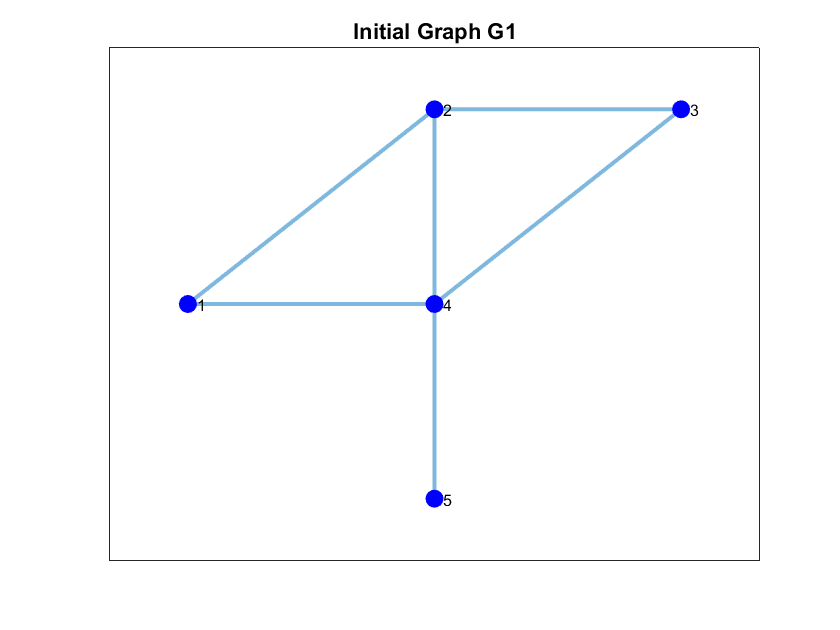

% GRAPH/DIGRAPH #1/2
Gx=[1 2 3 2 2];
Gy=[1 2 2 1 0];


% GRAPH #1
edgesG1 = [1 2; 1 4; 2 3; 2 4; 3 4; 4 5];
figure; G1 = graph(edgesG1(:,1),edgesG1(:,2));
plot(G1,'XData',Gx,'YData',Gy,'MarkerSize',8,'NodeColor','b', 'LineWidth',2);
xticks([]); yticks([]); title('Initial Graph G1')

A=[0 1 0 1 0; 1 0 1 1 0; 0 1 0 1 0; 1 1 1 0 1; 0 0 0 1 0];
D=diag([2 3 2 4 1]);
L=D-A;

% CASE 1 - limit case
eps = 0.25;
P = eye(5)-eps*L

P =     0.5000    0.2500         0    0.2500         0
    0.2500    0.2500    0.2500    0.2500         0
         0    0.2500    0.5000    0.2500         0
    0.2500    0.2500    0.2500         0    0.2500
         0         0         0    0.2500    0.7500


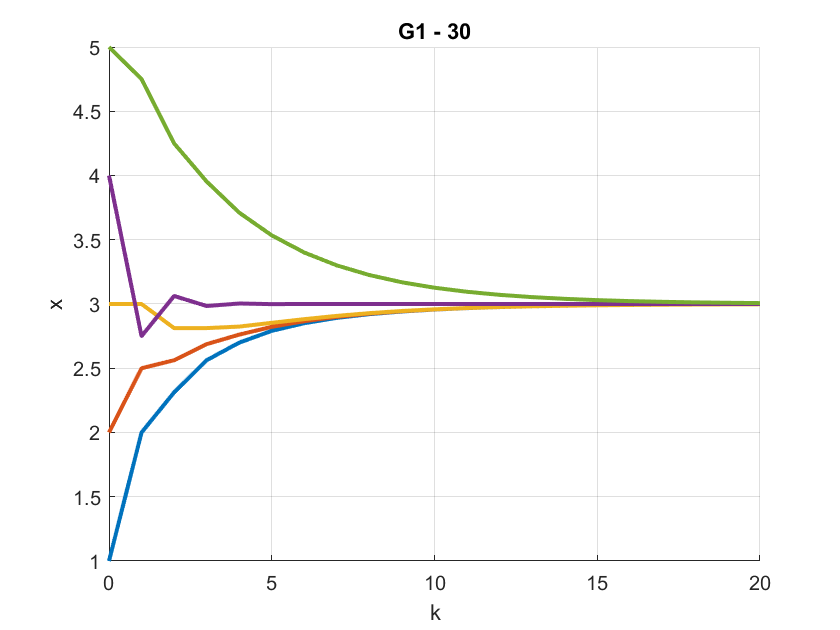

figure
x0=[1,2,3,4,5]';
%
xall=[]; kall=[];
for k=0:20; xall=[xall, P^k*x0]; kall=[kall, k]; end
xlabel('k'); ylabel('x'); hold on; grid on
plot(kall,xall,'LineWidth',2); title('G1 - 30')

#### STEP 1: Consensus of the agents

- Define communication graph (primitive P)

- Compute a consensus step and feed it to the corresponding UGV until consensus - the UGVs are massless points

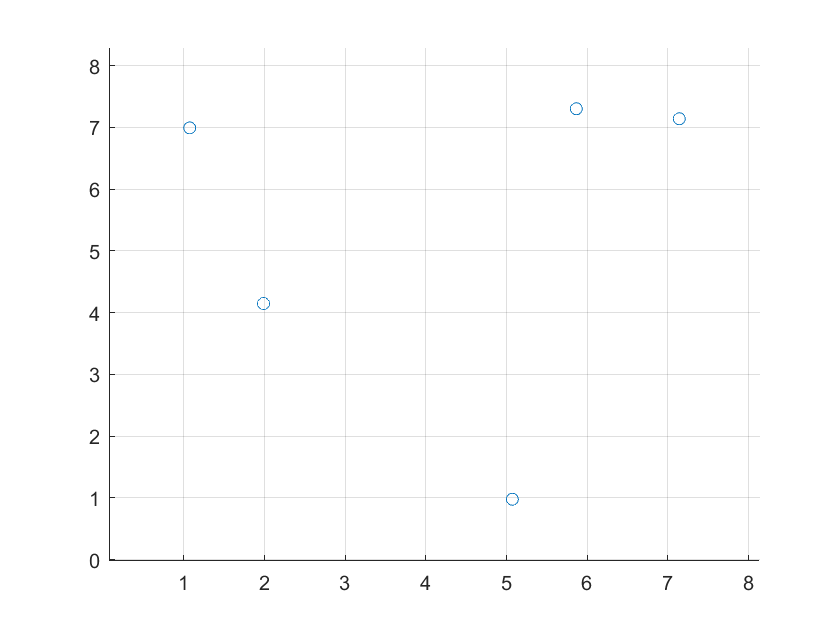


x0=randi(7,[2,5])';
e=0.1*randn([2,5])';
x0=x0+e;
%initial conditions
figure;
hold on;
grid on;
plot(x0(:,1),x0(:,2),"o");
xlim([min(x0(:,1))-1,max(x0(:,1))+1]);
ylim([min(x0(:,2))-1,max(x0(:,2))+1]);

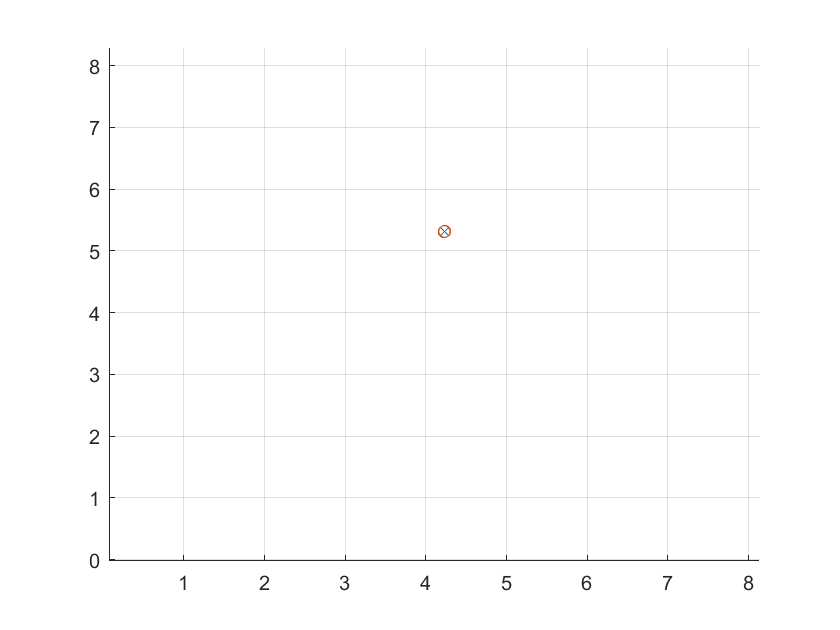

figure;
hold on;
grid on;
xc=mean(x0);
plot(xc(:,1),xc(:,2),"X");
x=zeros(size(x0));
hplot=plot(x0(:,1),x0(:,2),"o");
xlim([min(x0(:,1))-1,max(x0(:,1))+1]);
ylim([min(x0(:,2))-1,max(x0(:,2))+1]);
ugv_traj=zeros(5,2,20);
for k=1:20
    x(:,1)=(P^k)*x0(:,1);   
    x(:,2)=(P^k)*x0(:,2);
    ugv_traj(:,:,k)=x;
    set(hplot,"XData",x(:,1),"YData",x(:,2));
    pause(1);
    drawnow;
end

xc=x(1,:); %final point

%prepare time vector
%first ugv trajectory
first_traj=squeeze(ugv_traj(1,:,:))

first_traj =     3.6975    3.9204    3.9374    4.0063    4.0532    4.0942    4.1259    4.1505    4.1694    4.1837    4.1946    4.2028    4.2089    4.2135    4.2170    4.2196    4.2216    4.2231    4.2242    4.2250
    6.4374    5.8340    5.4880    5.3501    5.2904    5.2718    5.2698    5.2745    5.2812    5.2877    5.2934    5.2980    5.3017    5.3045    5.3067    5.3084    5.3096    5.3106    5.3113    5.3119


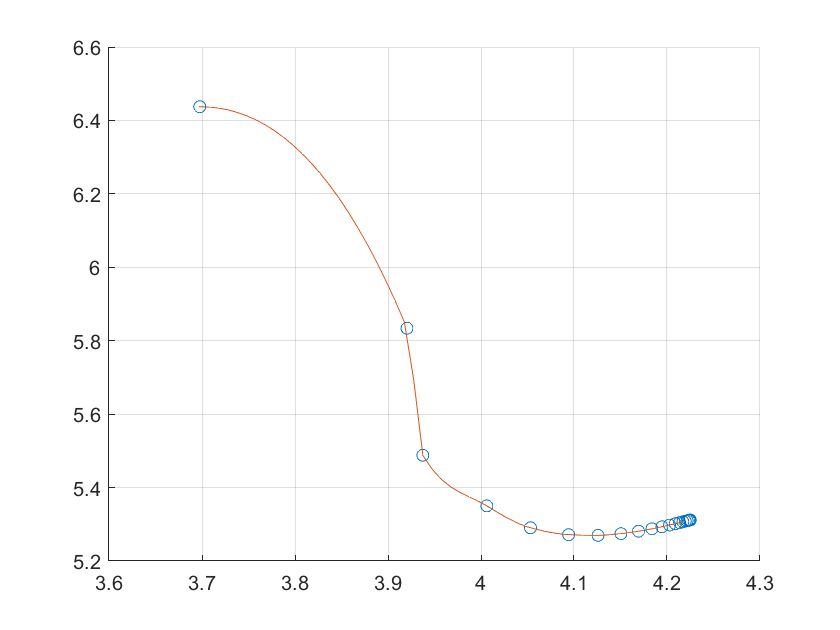

p_x=first_traj(1,:);
p_y=first_traj(2,:);
xx = p_x(1):0.01:p_x(end);
yy = interp1(p_x,p_y,xx,'pchip');
figure;
hold on;
grid on;
plot(p_x,p_y,'o',xx,yy);

unicycle.ic.x=p_x(1);
unicycle.ic.y=p_y(1);
%ts=timeseries(first_traj(:,2:end)');
ts=timeseries([xx;yy]');
angles=atan2(yy,xx);
ts_theta=timeseries(angles);

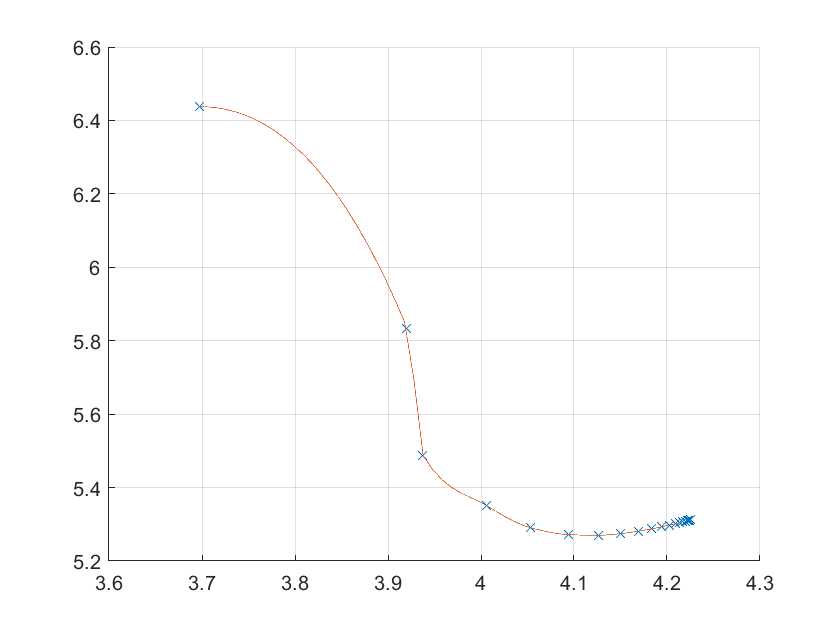

%run simulink
%plot trajectory
figure;
hold on;
grid on;
plot(p_x,p_y,"X");
plot(p.signals.values(:,1),p.signals.values(:,2));

#### STEP 2: Movement of UGV

- Get the drone landing point 

- Design a trajectory according to some criterium (fastest, best, parabula...) and set it for each UGV

figure;
t=0:0.01:5;
hold on;
grid on;
hplot=plot(xc(1),xc(2),"o");

m=max(abs(xc(1)-1),abs(xc(2)));
xlim([-m-1,m+1]);
ylim([-m-1,m+1]);
xpast=zeros(2,5/0.01);
for k=1:length(t)
    x(1)=xc(1)-1+cos(2*pi*t(k));   %circle with center (xc(1)-1,xc(2)) and unitary radius (ccw motion)
    x(2)=xc(2)+sin(2*pi*t(k)); 
    set(hplot, "XData",x(1),"YData",x(2));
    drawnow;
end

#### STEP 3: Drone landing

- Design a trajectory for the drone to its landing point according to some criterium.

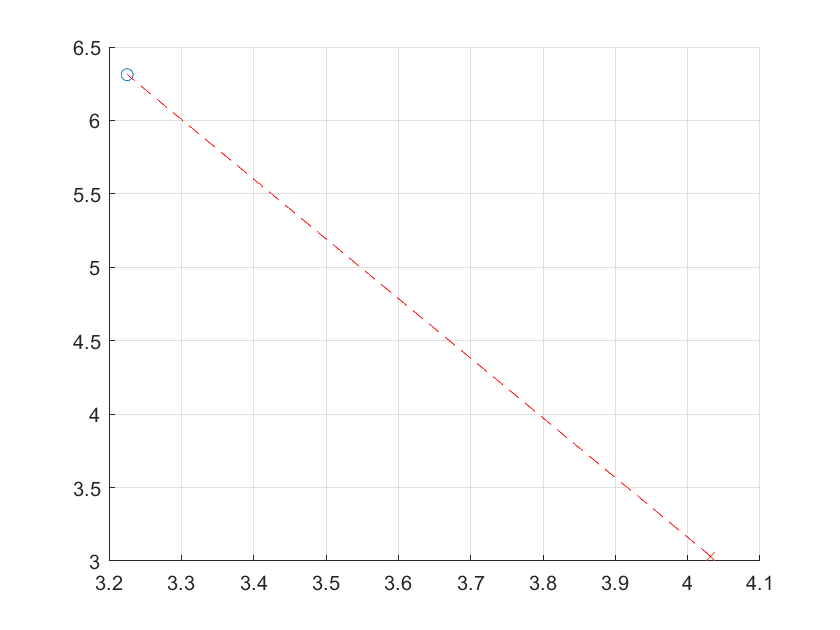

%circle moving
xd=randi(7,[1,2])';
e=0.1*randn([1,2])';
xd=xd+e; %drone position
xg=x(1,:); %final position of trajectory
tf=5;
A=[0,0,0,1,0,0,0,0;
   0,0,0,0,0,0,0,1;
   tf^3,tf^2,tf,1,0,0,0,0;
   0,0,0,0,tf^3,tf^2,tf,1;
   0,0,1,0,0,0,0,0;
   0,0,0,0,0,0,1,0;
   3*tf^2,2*tf,1,0,0,0,0,0;
   0,0,0,0,3*tf^2,2*tf,1,0];
b=[xd(1),xd(2),xg(1),xg(2),0,0,0,0]';
par=A\b;

%figure
figure;
hold on;
grid on;
plot(xg(1),xg(2),"O"); %UGV
plot(xd(1),xd(2),"X"); %UAV
t=0:0.01:tf;
xdes=[par(1)*t.^3+par(2)*t.^2+par(3)*t+par(4);
    par(5)*t.^3+par(6)*t.^2+par(7)*t+par(8)];
plot(xdes(1,:),xdes(2,:),"r--");

UGV moving (simulink)